*Definicion de los parametros del modelo de planta+controlador, sirve al archivo de Simulink al iniciar.*

## Constantes de la planta

Parametros electricos del motor

pares_polos = 2;
V_dc = 12; %[V]

R = 2.0; %[ohm]
L = 1.63e-3;  %[H]
k_e = 0.01; %[V*s/rad] Cte. BEMF de Fase
k_t = 2 * k_e;  %[N*m/A] Cte. de torque en six step.


Mecanica de las dos inercias

J1 = 5.1e-5; %[kg*m^2] Rotor + iman impulsor
J2 = 1.0e-6; %[kg*m^2] barra agitadora

Acople magnetico

Na = 1; % pares de polos del acople dipolar
delta_crit = pi / (2*Na); % [rad] angulo critico de desenganche
T_max = 10.5e-3; %[N*m] falta medir, torque de pull-out.

Friccion seca + viscosa

w_0f = 5.0;     %[rad/s] Suavizado numerico de tanh
T_C1 = 2e-4;    %[N*m] Friccion seca del lado motor
b_1 = 1e-6;     %[N*m*s/rad] Friccion viscosa lado motor
T_C2 = 1e-4;    %[N*m] friccion seca lado barra-fondo
b_2 = 1e-6;     %[N*m*s/rad] friccion viscosa barra


Carga del fluido y escenario de ensayo

b_fl_0 = 0.0;   %[N*m*s/rad] Termino viscoso inicial (aire ~ 0)
c_fl_0 = 0.0;   %[N*m*s^2/rad^2] Termino cuadratico inicial
db_fl = 5e-6;   %[N*m*s/rad] Esclaon laminar al agregar fluido.
dc_fl = 1e-7;   %[N*m*s^2/rad^2] Escalon turbulento.

Controlador PI Discreto y etapa PWM

f_pwm       = 18000;      % [Hz]  ESC_DEFAULT_PWM_FREQ_HZ
dt_c        = 0.002;      % [s]   RPM_PI_DT_SECONDS (TIM4 cada 2 ms)
u_min       = 100;        % [-]   RPM_PI_CANONICAL_MIN
u_max       = 2000;       % [-]   RPM_PI_CANONICAL_ARR
d_min       = u_min / u_max; % [-] = 0.05 en lazo cerrado
d_max       = 1.0;        % [-]
Kp          = 1.0;       % [-]   ESC_DEFAULT_KP_RPM (en modelo_simulacion.tex tambien usan 0.28)
Ki          = 4.0;       % [1/s] ESC_DEFAULT_KI_RPM
Kd          = 0.00;       % [-]   ESC_DEFAULT_KD_RPM (fijo en 0 en algoritmo v2)
n_ref       = 1000;       % [rpm] Consigna de velocidad de prueba

Sensor virtual ZC

f_t         = 180000;     % [Hz] Frecuencia de TIM2 (72 MHz / (399 + 1))
M_zc        = 2;          % [-]  ZCP_BUFFER_SIZE (promedio movil de M periodos)
P_valid_min = 50;         % [ticks] ZCP_VALID_MIN_THRESHOLD
P_valid_max = 50000;      % [ticks] ZCP_VALID_MAX_THRESHOLD
P_min       = 200;        % [ticks] SPEED_MAX
P_max       = 14000;      % [ticks] SPEED_MIN
zc_tol      = 0.25;       % [-]  SPEED_TOLERANCE_PCT / 100
zcp_to_check = 4;         % [-]  ZCP_TO_CHECK (cruces consistentes para pasar a CLOSEDLOOP)
n_ciego     = 350;        % [rpm] Zona ciega del comparador LM339 (300..400 rpm en banco)
tau_stall   = 0.200;      % [s]  TIMEOUT_MOTOR_STALL_MS = 200 ms

Arranque open loop SPWM

T_arr       = 3.0;        % [s]  ESC_DEFAULT_STARTUP_DURATION_MS = 3000
fe_0        = 2.09;       % [Hz] ESC_DEFAULT_STARTUP_INITIAL_FREQUENCY_MILLIHZ = 2090
fe_f        = 9.28;       % [Hz] ESC_DEFAULT_STARTUP_FINAL_FREQUENCY_MILLIHZ = 9280
A_0         = 0.20;       % [-]  ESC_DEFAULT_STARTUP_INITIAL_AMPLITUDE_PERMILLE = 200
A_f         = 1.00;       % [-]  ESC_DEFAULT_STARTUP_FINAL_AMPLITUDE_PERMILLE = 1000
d_handoff   = 0.45;       % [-]  Duty fijo en RUNNING tras terminar rampa (startup.c)
t_run_max   = 4.5;        % [s]  RUNNING_RESTART_TIMEOUT_MS = 4500 ms
t_brake     = 0.5;        % [s]  RUNNING_RESTART_BRAKE_MS = 500 ms

Linealizacion por pequeñas señales (Franklin 9.2.1)

n_0 = 1000;     % [rpm] punto de operacion
w_0 = pi/30*n_0;    %[rad/s] pto. de operacion
b_fl = db_fl; c_fl = dc_fl;
TL_tot = b_fl*w_0 + c_fl*w_0^2 + T_C2 + b_2*w_0;
delta_eq = asin(TL_tot / T_max) / Na;
I_0 = (TL_tot + T_C1 + b_1*w_0 ) / (2*k_e);
d_0 = (2*R*I_0 + 2*k_e*w_0) / V_dc;

B1_eq = b_1;
B2_eq = b_2 + b_fl + 2*c_fl*w_0;
K_eff = Na * T_max *cos(Na * delta_eq);
A = [ -R/L,      -k_e/L,        0,          0;
       2*k_e/J1, -B1_eq/J1,     0,         -K_eff/J1;
       0,         0,           -B2_eq/J2,   K_eff/J2;
       0,         1,           -1,          0 ];
B = [ V_dc/(2*L); 0; 0; 0 ];
C = [ 0, 30/pi, 0, 0 ];
G_lin = tf(ss(A, B, C, 0));         % G(s) = d_n1(s) / d_duty(s)  [rpm / duty]
G_pi = G_lin / u_max;   % [rpm / cuenta_PWM]

Controlador PI 

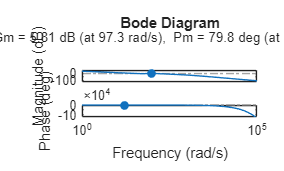

tau_0 = 15*(M_zc + 1) / (pares_polos * n_0) + dt_c/2;
G_pi_ret = G_pi * exp(-tau_0 * tf('s'));

C_s = pid(0.2, 8.0);
C_z = c2d(C_s, dt_c, 'tustin');

margin(C_s * G_pi_ret);